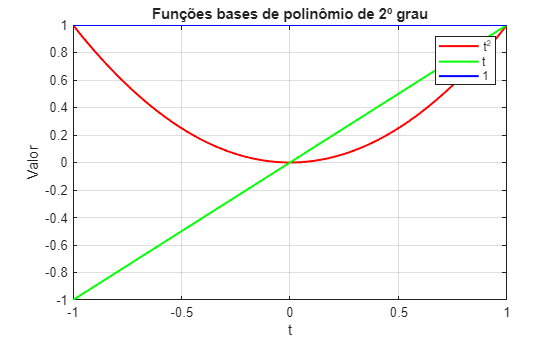

% Exercícios Computacionais - Semana 2
% Aluno: João Vitor Miranda Sousa, N° USP: 14802702

%% Questão 1 - Polinômio de segundo grau
% Polinômio: P2(t) = a*t^2 + b*t + c, t ∈ [-1, 1]

% Intervalo do tempo
t = -1:0.01:1;

% (a) Funções base: t^2, t e 1
base1 = t.^2;
base2 = t;
base3 = ones(size(t));

figure;
plot(t, base1, 'r', 'LineWidth', 1.5); hold on;
plot(t, base2, 'g', 'LineWidth', 1.5);
plot(t, base3, 'b', 'LineWidth', 1.5); grid on;
title('Funções bases de polinômio de 2º grau');
xlabel('t'); ylabel('Valor');
legend('t^2','t','1');

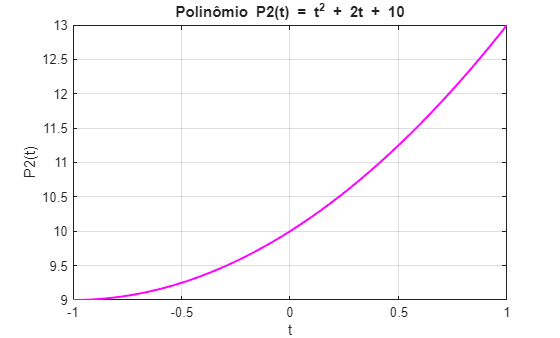


% (b) Polinômio com a=1, b=2, c=10
a = 1; b = 2; c = 10;
P2 = a*t.^2 + b*t + c;

figure;
plot(t, P2, 'm', 'LineWidth', 1.5); grid on;
title('Polinômio P2(t) = t^2 + 2t + 10');
xlabel('t'); ylabel('P2(t)');



%% Questão 2 - Produto escalar
% g(t) = 5t^2 + 2t + 9
% h(t) = sin(2t) * log(5 + 3t)
% t ∈ [-1, 1]

% Definição das funções (funções anônimas no MATLAB)
g = @(t) 5*t.^2 + 2*t + 9;
h = @(t) sin(2*t).*log(5 + 3*t);

% Produto escalar via integração numérica
produto_escalar = integral(@(t) g(t).*h(t), -1, 1);

% Mostrar resultado
disp(['Produto escalar <g,h> = ', num2str(produto_escalar)]);

Produto escalar <g,h> = 9.2327




%% Questão 3 - Aproximação por Série de Taylor
% Nesta questão, vamos considerar o sinal:
%   x(t) = cos(10πt)
% e fazer sua expansão em série de Taylor em torno de t=0,
% usando as 5 primeiras bases de representação do sinal.
% Para isso, será utilizado o comando "taylor" do Symbolic Math Toolbox.

% Definição simbólica da variável e do sinal
syms t
x = cos(10*pi*t);

% Expansão de Taylor de x(t) em torno de t=0
% 'Order',10 → gera termos até t^8 (5 primeiros termos da série de Taylor)
x_taylor5 = taylor(x, t, 'ExpansionPoint', 0, 'Order', 10);

% Exibir no console a expressão simbólica encontrada
disp('Série de Taylor (5 primeiros termos):');

Série de Taylor (5 primeiros termos):


pretty(simplify(x_taylor5))

         8  8           6  6          4  4
156250 pi  t    12500 pi  t    1250 pi  t         2  2
------------- - ------------ + ----------- - 50 pi  t  + 1
      63              9             3



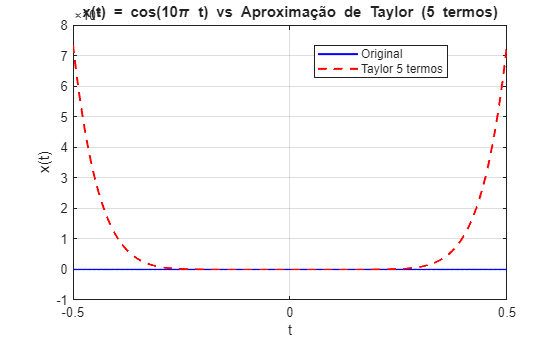


% Criação do vetor de tempo para comparação numérica
% Aqui consideramos o intervalo t ∈ [-0.5, 0.5] com 2000 pontos
t_vals = linspace(-0.5, 0.5, 2000);

% Cálculo do sinal original
x_original = cos(10*pi*t_vals);

% Cálculo da aproximação de Taylor substituindo os valores de t
x_aprox = double(subs(x_taylor5, t, t_vals));

% Plotagem dos resultados
figure;
plot(t_vals, x_original, 'b', 'LineWidth', 1.5); hold on;
plot(t_vals, x_aprox, 'r--', 'LineWidth', 1.5); grid on;

% Ajustes de título, eixos e legenda
title('x(t) = cos(10\pi t) vs Aproximação de Taylor (5 termos)');
xlabel('t'); ylabel('x(t)');
legend('Original','Taylor 5 termos','Location','best');